**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Autors: P.Ozga & P.Pramod 

dateset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

dateset from: by `Mustanger from kaggle link:`

https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input

### Toolbox: Statistics and Machine Learning & Deep Learning

## Get the path to the dataset and show first 5 sample.

close all;
% Get the path to the dataset and show first 5 samples
fpath = fullfile(pwd,'wine-quality.csv');                         % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
firstFive = head(fname, 5);                                       % Display first 5 rows
verticalView = array2table(firstFive.Variables', ...
    'VariableNames', strcat("Sample", string(1:5)), ...
    'RowNames', fname.Properties.VariableNames);
disp(verticalView);

                            Sample1    Sample2    Sample3    Sample4    Sample5
                            _______    _______    _______    _______    _______

    fixed acidity                7        6.3        8.1        7.2        7.2 
    volatile acidity          0.27        0.3       0.28       0.23       0.23 
    citric acid               0.36       0.34        0.4       0.32       0.32 
    residual sugar            20.7        1.6        6.9        8.5        8.5 
    chlorides                0.045      0.049       0.05      0.058      0.058 
    free sulfur dioxide         45         14         30         47         47 
    total sulfur dioxide       170        132         97        186   

nonNumericCols = varfun(@isnumeric, fname);     % Check each columns
nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
if ~isempty(nonNumericColsNames)                %is numeric or no-numeric?
    disp('Database is non-numeric.');
    disp(nonNumericColsNames);
else
    disp('Each columns is numeric.');
end

Each columns is numeric.


% Numeric summary
numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
numericData = fname(:, numericCols);
minVals = varfun(@min, numericData, 'OutputFormat', 'uniform');
maxVals = varfun(@max, numericData, 'OutputFormat', 'uniform');
summaryVertical = table(minVals', maxVals', 'VariableNames', {'Min', 'Max'},'RowNames', numericData.Properties.VariableNames);
disp(summaryVertical);

                              Min       Max 
                            _______    _____

    fixed acidity               3.8     14.2
    volatile acidity           0.08      1.1
    citric acid                   0     1.66
    residual sugar              0.6     65.8
    chlorides                 0.009    0.346
    free sulfur dioxide           2      289
    total sulfur dioxide          9      440
    density                 0.98711    1.039
    pH                         2.72     3.82
    sulphates                  0.22     1.08
    alcohol                       8     14.2
    quality                       3        9



Class Distribution

qualityCounts = countcats(categorical(fname.quality));
uniqueClasses = unique(fname.quality);
for i = 1:length(uniqueClasses)
    fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));
end

Class 3 has 20 samples
Class 4 has 163 samples
Class 5 has 1457 samples
Class 6 has 2198 samples
Class 7 has 880 samples
Class 8 has 175 samples
Class 9 has 5 samples


## Normalization all data

X = fname{:, 1:11};                  % Features (first 11 columns)
Y = fname{:, 12};                    % Quality rating (12th column)
X = normalize(X, 'range');           % Min-Max normalization

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## Konwersja etykiet do formatu klasyfikacyjnego (one-hot)

Y_categorical = categorical(Y);
Y_dummy = dummyvar(Y_categorical);  % One-hot encoding

## Split the Data into Training and Test Sets:

### about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

cv = cvpartition(Y_categorical, 'KFold', 5, 'Stratify', true); % K-Fold cross-validation
X_train = X(training(cv, 1), :);             % For the first fold
Y_train = Y_dummy(training(cv, 1), :);       % For the first fold
X_test = X(test(cv, 1), :);                  % For the first fold
Y_test = Y_dummy(test(cv, 1), :);

Compute weight for class

classCounts = countcats(categorical(Y));
totalSamples = sum(classCounts);
classWeights = totalSamples ./ classCounts;

## Create and Train the MLP (Multilayer Perceptron) Network:

### about `feedforwardnet `function, link: https://ch.mathworks.com/help/deeplearning/ref/feedforwardnet.html

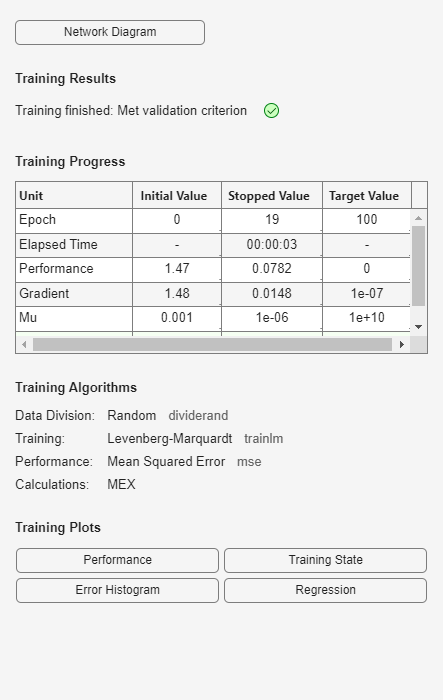

hiddenLayerSize = 12;
net = feedforwardnet(hiddenLayerSize);       % MLP for classification
net.performFcn = 'crossentropy';             % Loss function for classification
net.trainFcn = 'trainlm';                    % Levenberg-Marquardt
net.trainParam.epochs = 100;
net.trainParam.show = 50;
%net.performParam.normalization = 'none';     %!
%net.trainParam.showWindow = false;  % Wyłączenie okna GUI podczas treningu

%net.performParam.classWeights = classWeights;  % Ustawienie wag dla klas

% Trening
[net, tr] = train(net, X_train', Y_train');

## Test the Network

Y_pred = net(X_test');           % Predict (column)
Y_pred_class = vec2ind(Y_pred);  % From prediction to labels
Y_true_class = vec2ind(Y_test'); % From labels to index

Calculate Precision, Recall, F1-score

confMat = confusionmat(Y_true_class, Y_pred_class);
numClasses = size(confMat, 1);
precision = zeros(numClasses,1);
recall = zeros(numClasses,1);
f1 = zeros(numClasses,1);

for i = 1:numClasses
    TP = confMat(i,i);
    FP = sum(confMat(:,i)) - TP;
    FN = sum(confMat(i,:)) - TP;
    precision(i) = TP / (TP + FP + eps);
    recall(i) = TP / (TP + FN + eps);
    f1(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i) + eps);
end

disp('Class | Precision | Recall | F1-score');

Class | Precision | Recall | F1-score


for i = 1:numClasses
    fprintf('  %2d   |   %.2f    | %.2f   |  %.2f\n', i, precision(i), recall(i), f1(i));
end

   1   |   0.00    | 0.00   |  0.00
   2   |   0.57    | 0.12   |  0.21
   3   |   0.55    | 0.52   |  0.54
   4   |   0.52    | 0.71   |  0.60
   5   |   0.45    | 0.26   |  0.32
   6   |   0.00    | 0.00   |  0.00
   7   |   0.00    | 0.00   |  0.00


macroPrecision = mean(precision);
macroRecall = mean(recall);
macroF1 = mean(f1);

fprintf('\nMacro-avg Precision: %.2f\n', macroPrecision);


Macro-avg Precision: 0.30


fprintf('Macro-avg Recall: %.2f\n', macroRecall);

Macro-avg Recall: 0.23


fprintf('Macro-avg F1-score: %.2f\n', macroF1);

Macro-avg F1-score: 0.24


## Ocena jakości klasyfikacji

accuracy = sum(Y_pred_class == Y_true_class) / length(Y_true_class);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 52.30%


## Confusion Matrix

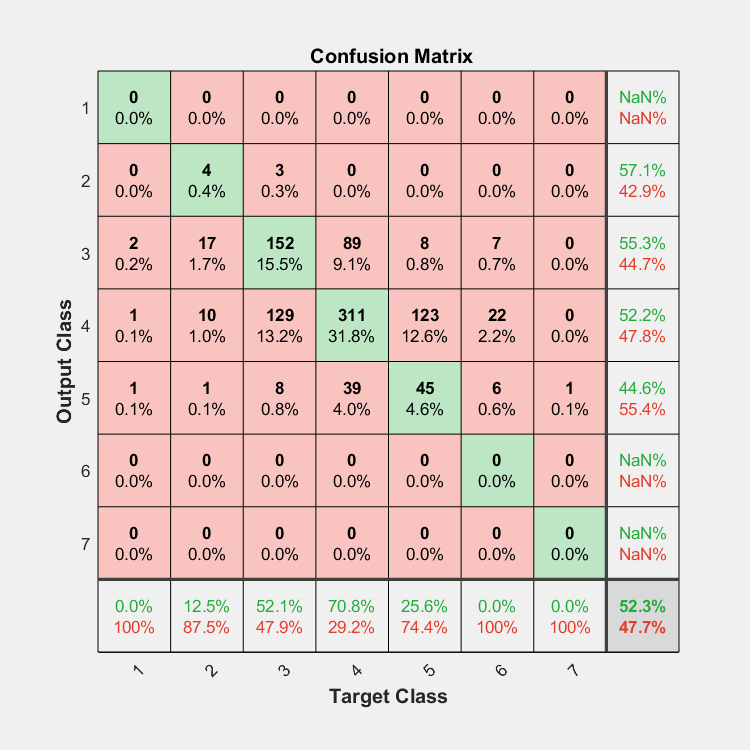

figure;
plotconfusion(Y_test', Y_pred);

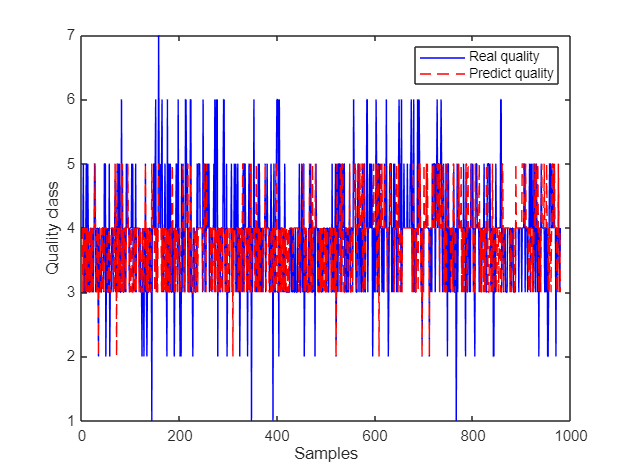

% Porównanie rzeczywistych i przewidywanych klas
figure;
plot(Y_true_class, 'b'); hold on;
plot(Y_pred_class, 'r--');
legend('Real quality', 'Predict quality');
xlabel('Samples');
ylabel('Quality class');